# University of Technology Sydney

#### **Sydney, Australia**

#### **A/Prof Ricardo P. Aguilera**

**7th August 2024**

# ADC Calibration (Inputs)

clc;
clear;

## **Data Acquisition **

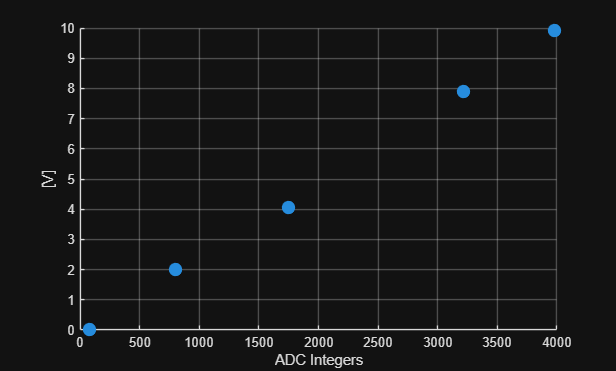

%data_calib_in1 = [ADC_Integer, Actual Voltage];
data_calib_in1 = [  80,      0;
                    800,    2;
                    1751,    4.06;
                    3212,   7.9;
                    3980,   9.931];

x = data_calib_in1(:,1); % ADC Integer 
y = data_calib_in1(:,2); % Actual voltage

figure(1)
scatter(x,y,100,"filled")
grid
xlabel('ADC Integers')
ylabel('[V]')

## Linear Regression

p = polyfit(x,y,1);

Slope:

p1 =  p(1)

p1 = 0.0025

Intercept (offset in 'y'):

p2 =  p(2)

p2 = -0.1787

## Verification

Estimated y values:

y_fit = p1*x+p2

y_fit =     0.0232
    1.8398
    4.2393
    7.9255
    9.8633


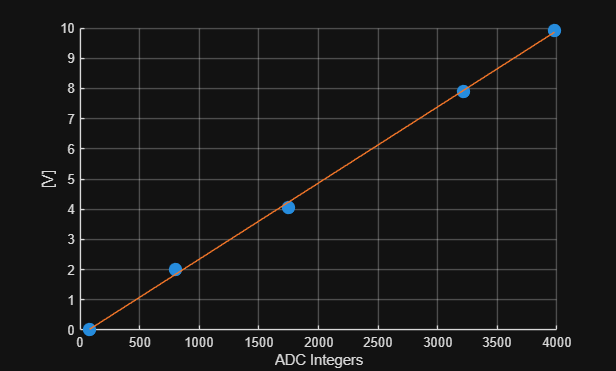

figure(2)
scatter(x,y,100,"filled")
grid
xlabel('ADC Integers')
ylabel('[V]')
hold on
plot(x,y_fit)
hold off

# PWM DAC Calibration (Outputs)

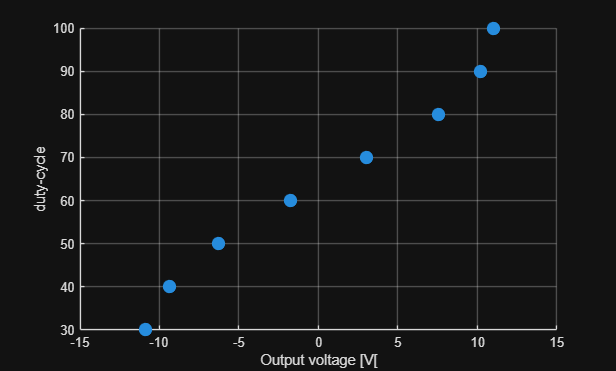

%data_calib_in1 = [Output_Voltage, duty_cycle; ]
data_calib_out1 = [  %-11.508,     0;
                     %-11.514,     10;
                     %-11.511,     20;
                     -10.899,     30;
                     -9.399,     40;
                     -6.306,     50;
                     -1.7738,     60;
                     3.0372,     70;
                     7.565,     80;
                     10.172,     90;
                     10.986,     100];

x = data_calib_out1(:,1); % Actual voltage
y = data_calib_out1(:,2); % ADC Integer


figure(3)
scatter(x,y,100,"filled")
grid
xlabel('Output voltage [V[')
ylabel('duty-cycle')

## Linear Regression

p = polyfit(x,y,1);

Slope:

p1 = p(1)

p1 = 2.7583

Intercept (offset in 'y'):

p2 = p(2)

p2 = 63.8338

## Verification

Estimated y values:

y_fit = p1*x+p2

y_fit =    33.7707
   37.9082
   46.4397
   58.9410
   72.2114
   84.7006
   91.8916
   94.1369


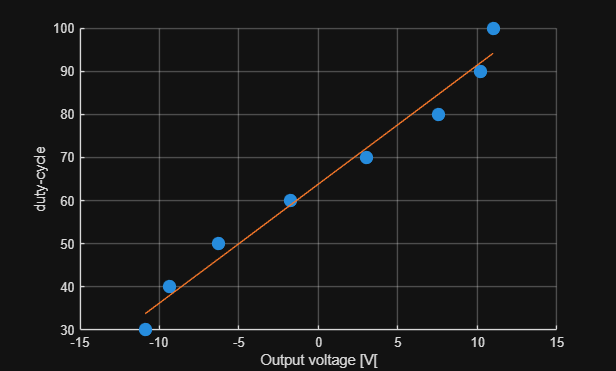

figure(2)
scatter(x,y,100,"filled")
grid
xlabel('Output voltage [V[')
ylabel('duty-cycle')
hold on
plot(x,y_fit)
hold off